test_distinction_multiplications

Loading Success!

Begin test!
----------------
OK!
OK!
Closing the Port ...
...
Completed!!
------------
Summary:
 Total tests: 2
 Total correct cases: 2
 Total wrong cases: 0


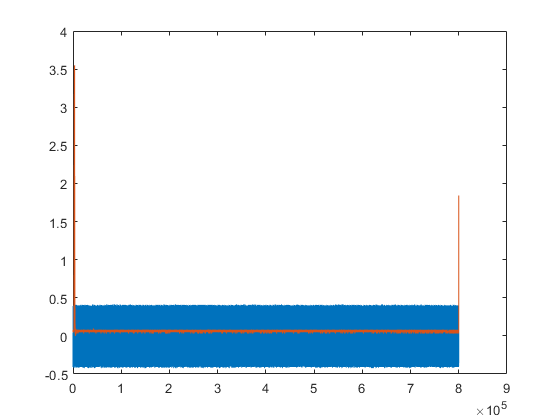


plot(traces_Y(1,:))
hold on 
plot(traces_trig(1,:))
hold off

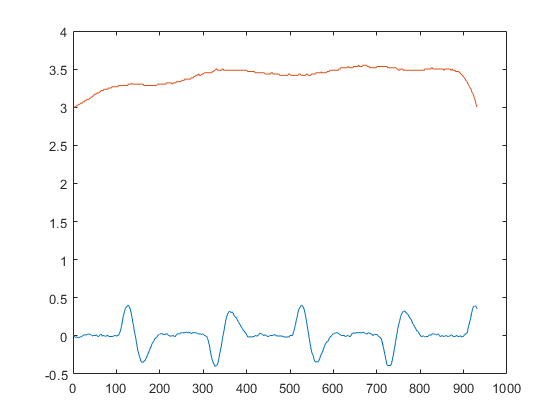

selectedTrace = traces_Y(1,traces_trig(1,:)>=3);
selectedTrig = traces_trig(1,traces_trig(1,:)>=3);
plot(selectedTrace)
hold on
plot(selectedTrig)
hold off

Sliding window correlation with the trace

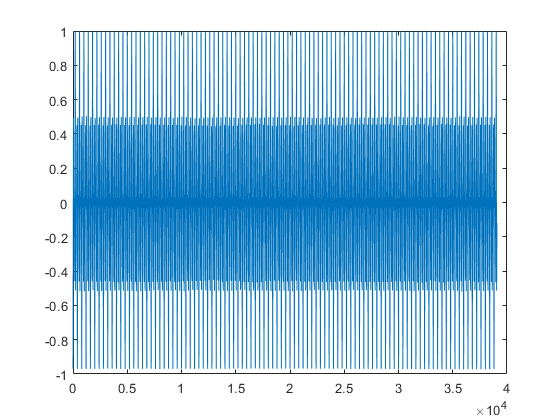

%Select the first 40000 samples
trace_2_shorted = traces_Y(2,1:40000);

sizeCorrMat = size(trace_2_shorted,2)-length(selectedTrace);

corrArr = zeros(1,sizeCorrMat);

for i = 1 : sizeCorrMat
    coef = corrcoef(selectedTrace,trace_2_shorted(i:(i-1)+length(selectedTrace)));
    corrArr(i) = coef(1,2);
end

plot(corrArr)

Sliding window euclidean distance with the trace

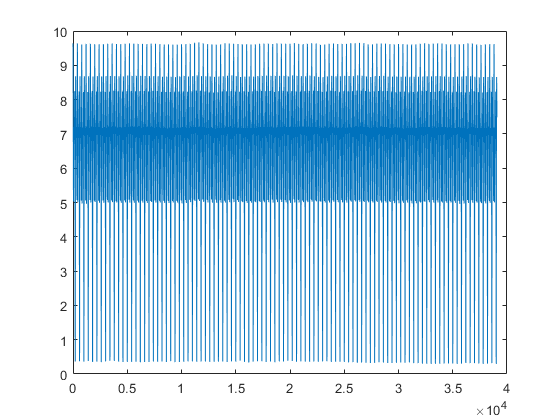

sizeDistMat = sizeCorrMat;

distArr = zeros(1,sizeDistMat);

for i = 1 : sizeDistMat
    distArr(i) =  norm(selectedTrace - trace_2_shorted(i:(i-1)+length(selectedTrace)));
end

plot(distArr)